## Dane wejściowe

clear all
load("data\mass_data.mat","Iyy","Mass")
load("data\enviroment_data.mat","dynamic_pressure","v_sound")
load("data\wing_geometry.mat","S","MAC")
load("data\flight_cases_data.mat", "mach")
load("data\longitudinal_data.mat")
load("data\longitudinal_dimnsional_derivatives.mat")


global i
i=1;
global o
o=3;
gainer=0;
mdl = 'dynamic_calc';
open_system(mdl)
iw(1) = linio('dynamic_calc/feedback',1,'input');
iw(2) = linio('dynamic_calc/q',1,'output');
linsys1 = linearize(mdl,iw);
linsys1.InputName = '\delta_E';
linsys1.OutputName='\theta'

linsys1 =
 
  A = 
                   alfa       theta           u    Actuator           q
   alfa          -1.108   -0.001991  -0.0002405      -2.002       0.961
   theta              0           0           0           0           1
   u              17.35      -32.15    -0.01396           0           0
   Actuator           0           0           0         -30           0
   q             -2.654    0.000695     0.00019      -80.64      -1.313
 
  B = 
             \delta_E
   alfa             0
   theta            0
   u                0
   Actuator         1
   q                0
 
  C = 
               alfa     theta         u  Actuator         q
   \theta         0         0         0         0         1
 
  D = 
           \delta_E
   \theta         0
 
Continuous-time state-space model.


gainer=-0.9026;
mdl = 'dynamic_calc';
open_system(mdl)
iw(1) = linio('dynamic_calc/feedback',1,'input');
iw(2) = linio('dynamic_calc/q',1,'output');
linsys2 = linearize(mdl,iw);
linsys2.InputName = '\delta_E';
linsys2.OutputName='\theta'

linsys2 =
 
  A = 
                   alfa       theta           u    Actuator           q
   alfa          -1.108   -0.001991  -0.0002405      -2.002       0.961
   theta              0           0           0           0           1
   u              17.35      -32.15    -0.01396           0           0
   Actuator           0           0           0         -30      0.9026
   q             -2.654    0.000695     0.00019      -80.64      -1.313
 
  B = 
             \delta_E
   alfa             0
   theta            0
   u                0
   Actuator         1
   q                0
 
  C = 
               alfa     theta         u  Actuator         q
   \theta         0         0         0         0         1
 
  D = 
           \delta_E
   \theta         0
 
Continuous-time state-space model.


impulse(linsys1,linsys2,300)
t=legend('bez stabilizacji', 'ze sprężeniem zwrotnym q')

t =   Legend (bez stabilizacji, ze sprężeniem zwrotnym q) with properties:

         String: {'bez stabilizacji'  'ze sprężeniem zwrotnym q'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.5399 0.7658 0.3468 0.0869]
          Units: 'normalized'

  Show all properties


t.Location="southeast"

t =   Legend (bez stabilizacji, ze sprężeniem zwrotnym q) with properties:

         String: {'bez stabilizacji'  'ze sprężeniem zwrotnym q'}
       Location: 'southeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.5399 0.1359 0.3468 0.0869]
          Units: 'normalized'

  Show all properties


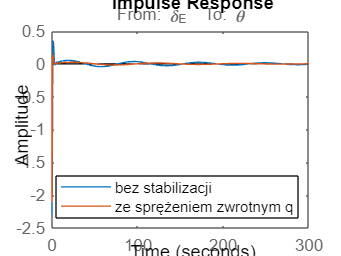

t.NumColumns=1;
saveas(t,'impuls.jpg')

## Wykresownik

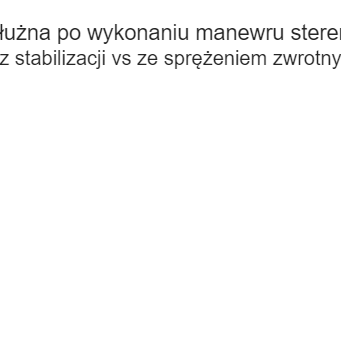

Unrecognized function or variable 'gainer'.

Error in Dyn_calculations>grapher (line 106)
    gainer=gainer(1);

global i
i=1;
global o
o=3;
gainer=[0, -0.9026];
grapher(1,3,'wzmoc.jpg')

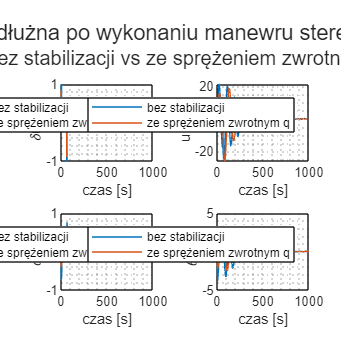

i=1;
o=3;
wyk= figure;
wyk.Position=[0 0 1000 1000];
wyk=tiledlayout(2,2,"TileSpacing","compact");
title(wyk,'Rakcja podłużna po wykonaniu manewru sterem wysokości')
subtitle(wyk,'bez stabilizacji vs ze sprężeniem zwrotnym q')
gainer=0;
simIn = Simulink.SimulationInput('dynamic_calc');
simIn = setModelParameter(simIn,'StartTime','0','StopTime','1000','FixedStep','0.001');
runIDs = Simulink.sdi.getAllRunIDs;
runID = runIDs(end);
dataset = Simulink.sdi.exportRun(runID);
out = sim(simIn);
u_t = out.u;
alfa_t = out.alfa;
theta_t=out.theta;
delta_t=out.delta;
gainer=-0.926;
runID = runIDs(end);
dataset = Simulink.sdi.exportRun(runID);
out = sim(simIn);
u_t2 = out.u;
alfa_t2 = out.alfa;
theta_t2=out.theta;
delta_t2=out.delta;
nexttile
plot(u_t.time,delta_t.Data,u_t2.time,delta_t2.Data)
xlabel('czas [s]')
ylabel('\delta_E [\circ]')
legend('bez stabilizacji', 'ze sprężeniem zwrotnym q')
grid minor
nexttile
plot(u_t.time,u_t.Data,u_t2.Time,u_t2.Data)
xlabel('czas [s]')
ylabel('u [ft/s]')
legend('bez stabilizacji', 'ze sprężeniem zwrotnym q')
grid minor
nexttile
plot(alfa_t.time,alfa_t.Data,alfa_t2.time,alfa_t2.Data)
xlabel('czas [s]')
ylabel('\alpha [\circ]')
legend('bez stabilizacji', 'ze sprężeniem zwrotnym q')
grid minor
nexttile
plot(theta_t.time,theta_t.Data,theta_t2.time,theta_t2.Data)
xlabel('czas [s]')
ylabel('\theta [\circ]')
legend('bez stabilizacji', 'ze sprężeniem zwrotnym q')
grid minor
saveas(wyk,'wzhhhc.jpg');

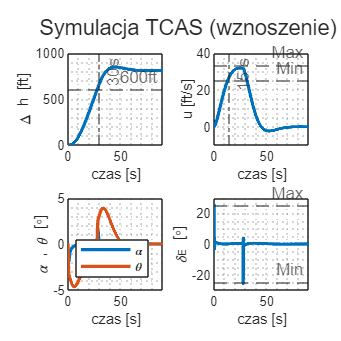

i=1;
o=3;
gainer=-0.926;
wyk= figure;
wyk.Position=[0 0 1000 1000];
wyk=tiledlayout(2,2,"TileSpacing","compact");
title(wyk,'Symulacja TCAS (wznoszenie)')
simIn = Simulink.SimulationInput('dynamic_calc');
simIn = setModelParameter(simIn,'StartTime','0','StopTime','90','FixedStep','0.001');
runIDs = Simulink.sdi.getAllRunIDs;
runID = runIDs(end);
dataset = Simulink.sdi.exportRun(runID);
out = sim(simIn);
u_t = out.u;
alfa_t = out.alfa;
theta_t=out.theta;
delta_t=out.delta;
h_t=out.h;
nexttile
plot(h_t.Time,h_t.Data,LineWidth=2)
axis([0, 90, 0, inf])
xline(30,'-.' ,{'30s'})
yline([600 1000],'--',{'600ft','1000ft'})
xlabel('czas [s]')
ylabel('\Delta h [ft]')
grid minor
nexttile
plot(u_t.Time,u_t.Data,LineWidth=2)
yline([1500/60 2000/60],'--',{'Min','Max'})
xline(15,'-.',{'15 s'})
grid minor
axis([0, 90, -10, 40])
xlabel('czas [s]')
ylabel('u [ft/s]')
nexttile
plot(alfa_t.Time,alfa_t.Data,theta_t.Time,theta_t.Data,LineWidth=2)
axis([0, 90, -5, 5])
legend('\alpha','\theta',Location='southeast')
grid minor
xlabel('czas [s]')
ylabel('\alpha , \theta [\circ]')
nexttile
plot(delta_t.Time,delta_t.Data,LineWidth=2)
axis([0, 90, -30, 30])
grid minor
yline([-25, 25],'--',{'Min', 'Max'})
xlabel('czas [s]')
ylabel('\delta_E [\circ]')
saveas(wyk,'TCAS.jpg')

function bodyer(row1,col1,file_namee)
global i
i=row1;
global o
o=col1;
end

function grapher(row1,col1,file_namee)
    global i
    i=row1;
    global o
    o=col1;
    wyk= figure;
    wyk.Position=[0 0 1000 1000];
    wyk=tiledlayout(2,2,"TileSpacing","compact");
    title(wyk,'Rakcja podłużna po wykonaniu manewru sterem wysokości')
    subtitle(wyk,'bez stabilizacji vs ze sprężeniem zwrotnym q')
    gainer=gainer(1);
    simIn = Simulink.SimulationInput('dynamic_calc');
    simIn = setModelParameter(simIn,'StartTime','0','StopTime','1000','FixedStep','0.001');
    runIDs = Simulink.sdi.getAllRunIDs;
    runID = runIDs(end);
    dataset = Simulink.sdi.exportRun(runID);
    out = sim(simIn);
    u_t = out.u;
    alfa_t = out.alfa;
    theta_t=out.theta;
    delta_t=out.delta;
    runID = runIDs(end);
    dataset = Simulink.sdi.exportRun(runID);
    out = sim(simIn);
    u_t2 = out.u;
    alfa_t2 = out.alfa;
    theta_t2=out.theta;
    delta_t2=out.delta;
    nexttile
    plot(u_t.time,delta_t.Data,u_t2.time,delta_t2.Data)
    xlabel('czas [s]')
    ylabel('\delta_E [\circ]')
    grid minor
    nexttile
    plot(u_t.time,u_t.Data)
    xlabel('czas [s]')
    ylabel('u [ft/s]')
    grid minor
    nexttile
    plot(alfa_t.time,alfa_t.Data)
    xlabel('czas [s]')
    ylabel('\alpha [\circ]')
    grid minor
    nexttile
    plot(theta_t.time,theta_t.Data)
    xlabel('czas [s]')
    ylabel('\theta [\circ]')
    grid minor
    saveas(wyk,file_namee);


end